# Tutorial 7: Control Simulations in CASPR

This tutorial will show how a simulation for testing controllers can be ran in CASPR for cable-driven robots. This tutorial will use the ideas from the following previous tutorials:

- `T1_load_robot.mlx`

- `T2_load_trajectory.mlx`

- `T5_inverse_dynamics.mlx`

- `T6_forward_dynamics.mlx`

This tutorial shows how to run controllers through two approaches:

- ControllerSimulator

- Writing your own time loop

## Setup (required for both approaches)

### Load the robot and trajectory

Load a robot as shown in `T1_load_robot.mlx `and` T2_load_trajectory.mlx`

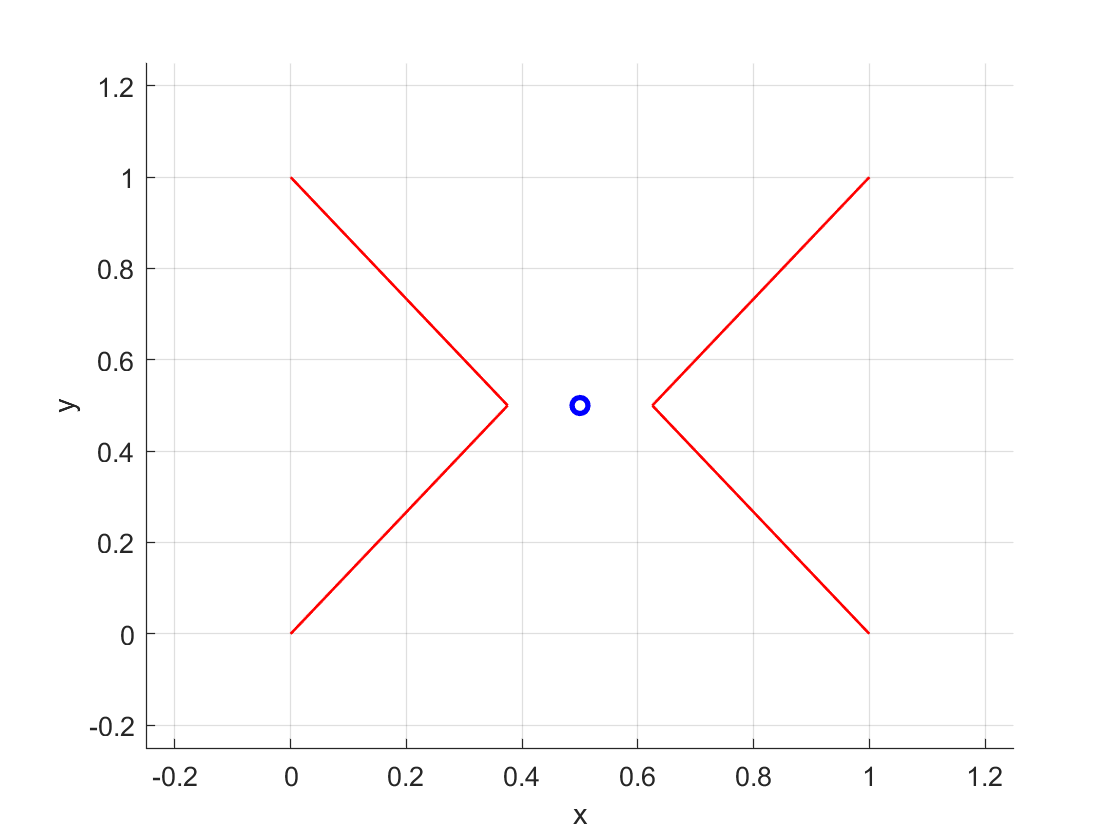

model_config = ModelConfig('Example planar XY');
cdpr_model = model_config.getModel('basic');
trajectory_ref = model_config.getJointTrajectory('example_quintic');
MotionSimulatorBase.PlotFrame(cdpr_model, model_config.displayRange, model_config.viewAngle); % Plot robot

### Create InverseDynamics solver

The inverse dynamics solver is required to resolve the cable force commands to be executed on the robot. In this example, a simple quadratic program (QP) solver will be used (refer to `T5_inverse_dynamics.mlx`). 

id_objective = IDObjectiveMinQuadCableForce(ones(cdpr_model.numCables,1));
id_solver = IDSolverQuadProg(cdpr_model, id_objective, ID_QP_SolverType.MATLAB);

### Create ForwardDynamics solver

This is needed in order to simulate the effects of the controller on a robot model. In practise, the forward dynamics would be replaced by a real robot. 

fd_solver = ForwardDynamics(FDSolverType.ODE113);

### Setup controller

Since there are many different methods to solve for the control problem, different controller can be setup to be used in CASPR. For the sake of example, the most common computed torque controller (CTC) with a quadratic program (QP) inverse dynamics solver will be shown in this example:

Kp_gains = 25*eye(cdpr_model.numDofs);
Kd_gains = 10*eye(cdpr_model.numDofs);
controller = ComputedTorqueController(cdpr_model, id_solver, Kp_gains, Kd_gains);

### Setup initial conditions

Set the initial conditions for the scenario

q_init = trajectory_ref.q{1} + [-0.1; 0.2; 0.1];
q_dot_init = trajectory_ref.q_dot{1};
q_ddot_init = trajectory_ref.q_ddot{1};

## 1) Solve using the ControllerSimulator

The Forward`KinematicsSimulator` provides the simplest way to run a "standard" forward kinematics simulation for a defined trajectory. 

First, create the simulator object using the robot model and the specified solver:

control_sim = ControllerSimulator(cdpr_model, controller, fd_solver, [], [], [], [], []);

Default options will be applied.


Next, run the simulator on the resulting cable lengths and cable lengths velocity over the specified time points with the initial joint pose and velocity:

control_sim.run(trajectory_ref, q_init, q_dot_init, q_ddot_init);

[INFO] Time : 0.000000
[INFO] Completion Percentage: 0.99%
[INFO] Time : 0.050000
[INFO] Completion Percentage: 1.98%
[INFO] Time : 0.100000
[INFO] Completion Percentage: 2.97%
[INFO] Time : 0.150000
[INFO] Completion Percentage: 3.96%
[INFO] Time : 0.200000
[INFO] Completion Percentage: 4.95%
[INFO] Time : 0.250000
[INFO] Completion Percentage: 5.94%
[INFO] Time : 0.300000
[INFO] Completion Percentage: 6.93%
[INFO] Time : 0.350000
[INFO] Completion Percentage: 7.92%
[INFO] Time : 0.400000
[INFO] Completion Percentage: 8.91%
[INFO] Time : 0.450000
[INFO] Completion Percentage: 9.90%
[INFO] Time : 0.500000
[INFO] Completion Percentage: 10.89%
[INFO] Time : 0.550000
[INFO] Completion Percentage: 11.88%
[INFO] Time : 0.600000
[INFO] Completion Percentage: 12.87%
[INFO] Time : 0.650000
[INFO] Completion Percentage: 13.86%
[INFO] Time : 0.700000
[INFO] Completion Percentage: 14.85%
[INFO] Time : 0.750000
[INFO] Completion Percentage: 15.84%
[INFO] Time : 0.800000
[INFO] Completion Percentag

The forward dynamics simulator can plot the resulting joint pose

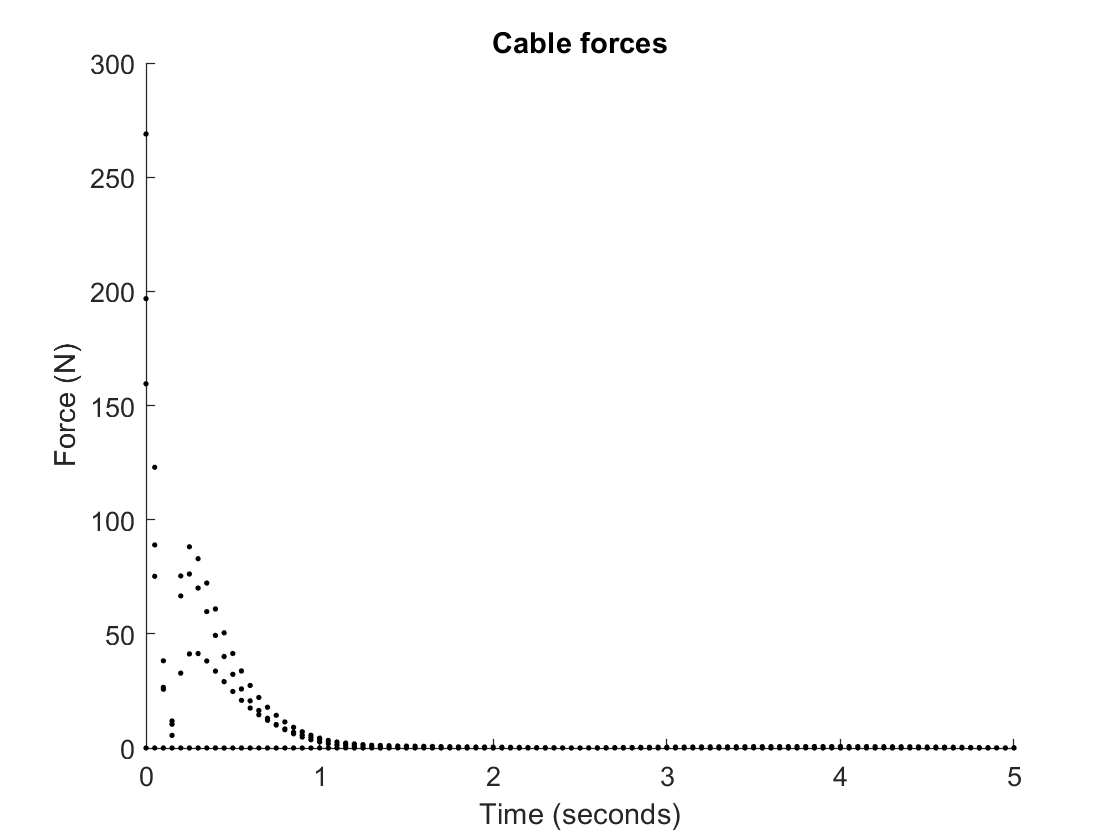

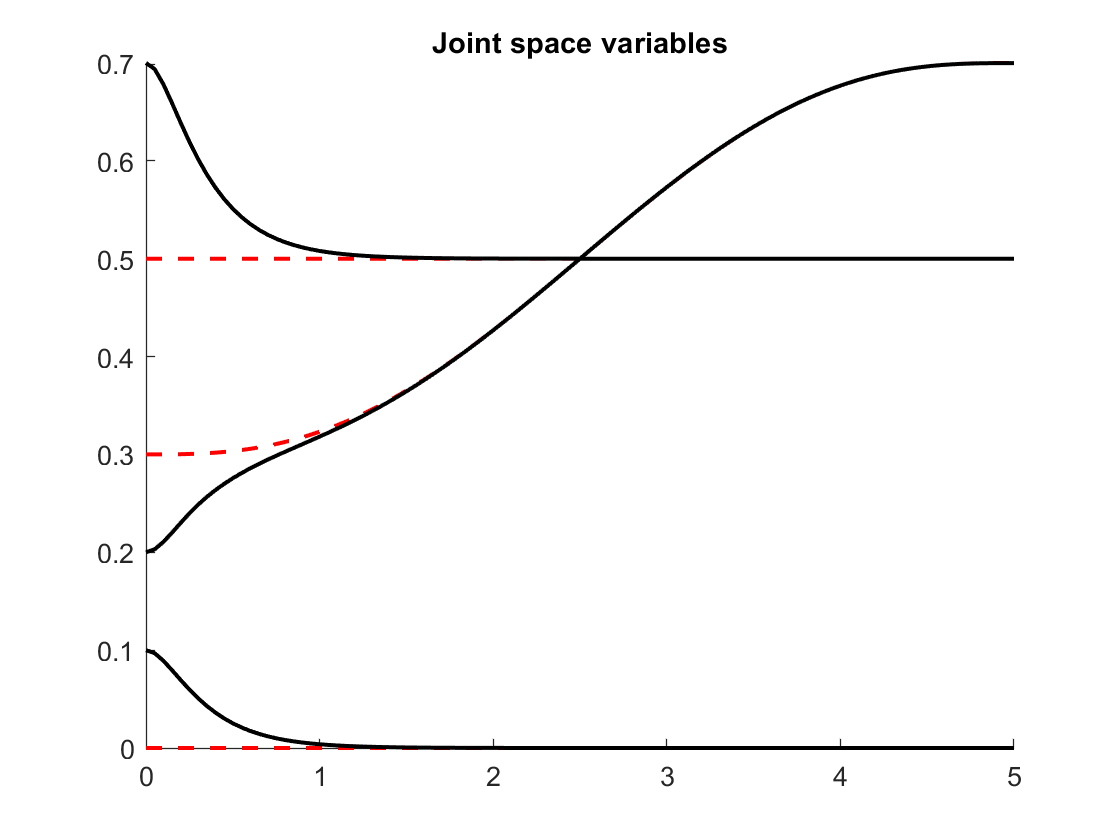

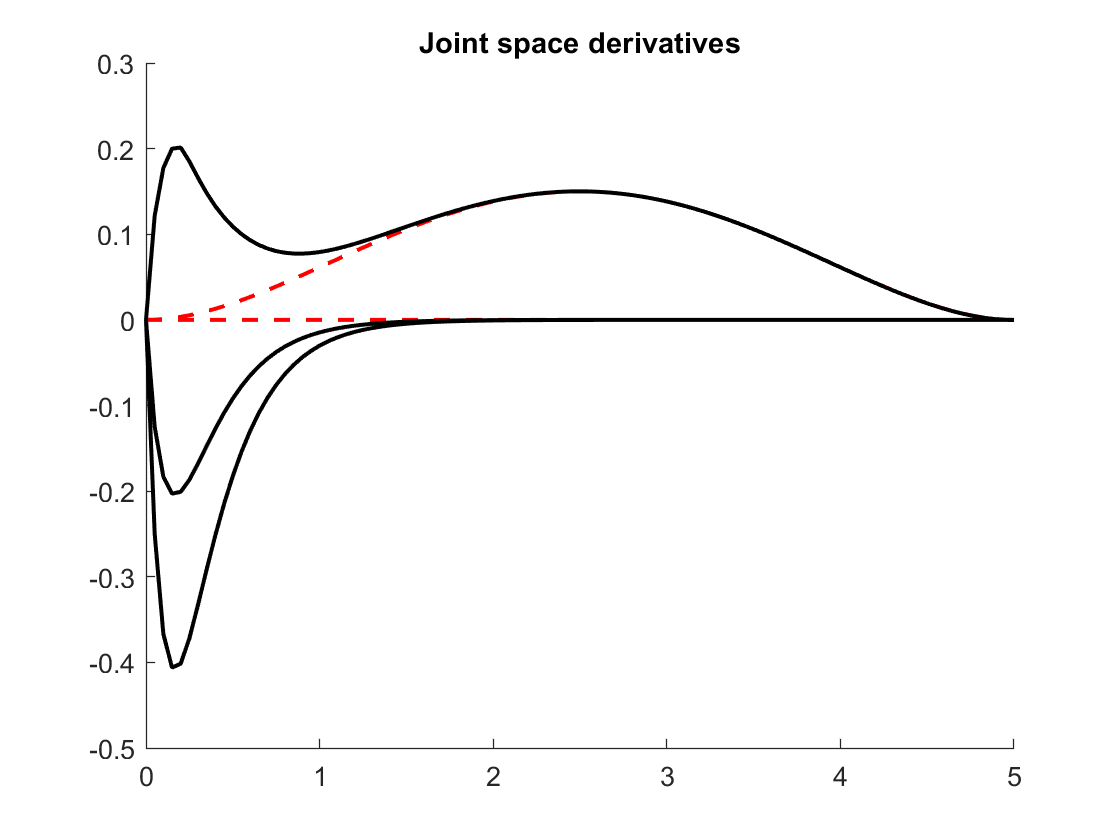

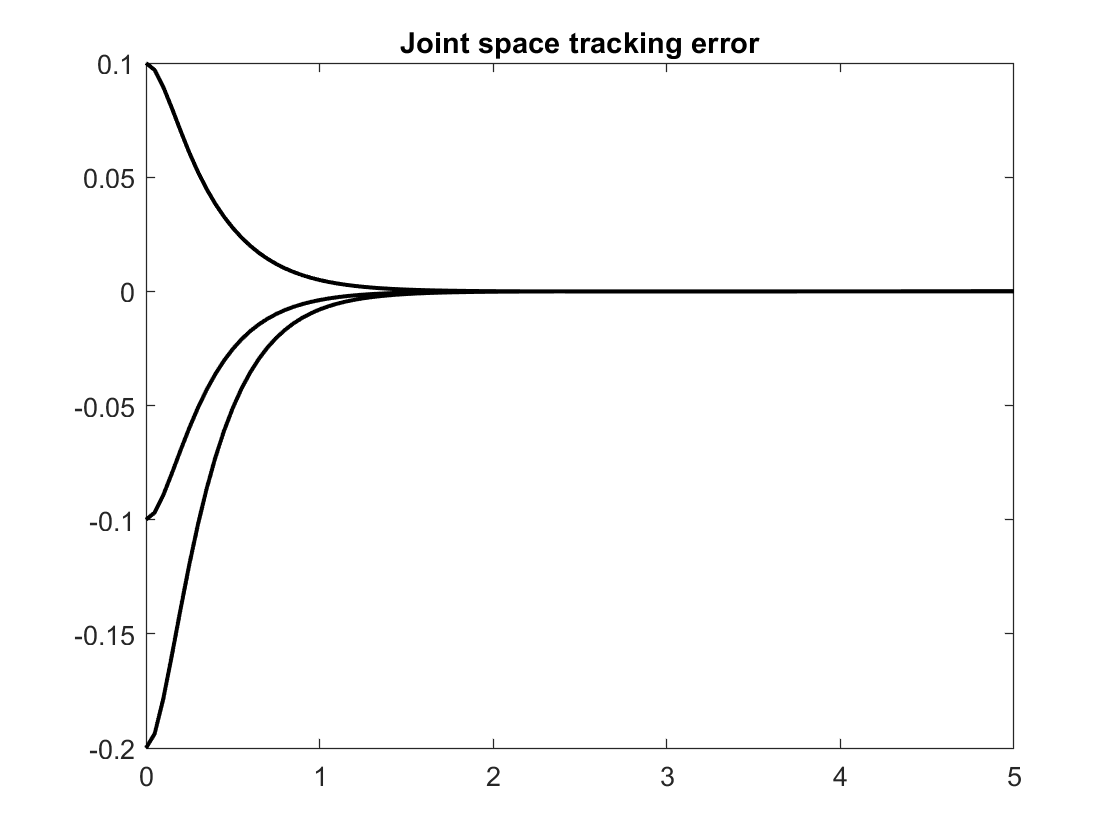

if control_sim.controllerExitType == ControllerExitType.NO_ERROR
    control_sim.plotCableForces();
    control_sim.plotJointSpaceTracking();
    control_sim.plotJointTrackingError();
else
    CASPR_log.Info('The controller simulation did not complete and hence nothing will be plotted')
end

## 2) Writing your own time loop

If you want more control over what is happening or customise the inner-workings during the simulation, it is recommended for you to write your own time loop. The following simple example is basically what happens within the `ControllerSimulator`.

First, create the variables (pre-allocate memory) required to store the solution from the inverse kinematics (cable lengths and cable lengths velocity):

q_soln = zeros(cdpr_model.numDofs, length(trajectory_ref.timeVector)); % Each column is the solution at each time step
q_dot_soln = zeros(cdpr_model.numDofs, length(trajectory_ref.timeVector)); % Each column is the solution at each time step
q_ddot_soln = zeros(cdpr_model.numDofs, length(trajectory_ref.timeVector)); % Each column is the solution at each time step
force_soln = zeros(cdpr_model.numActuators, length(trajectory_ref.timeVector)); % Each column is the solution at each time step

Setup some initial variables for the joint space:

q_soln(:, 1) = q_init;
q_dot_soln(:, 1) = q_dot_init;
q_ddot_soln(:, 1) = q_ddot_init;

Next, loop through the trajectory as a function of time:

for t = 1:length(trajectory_ref.timeVector)-1

Execute the controller with the current joint states and reference trajectory (note that zero disturbance is applied) to determine the cable force command:

    [force_soln(:, t), ~, ~, controller_exit_type] = controller.execute(q_soln(:, t), q_dot_soln(:, t), q_ddot_soln(:, t), trajectory_ref.q{t}, trajectory_ref.q_dot{t}, trajectory_ref.q_ddot{t}, zeros(cdpr_model.numDofs, 1), trajectory_ref.timeVector(t)); 

If controller exit type is not ControllerExitType.NO_ERROR, then it means that the controller didn't run to completion and hence should quit from the time loop.

    if controller_exit_type ~= ControllerExitType.NO_ERROR
        CASPR_log.Info('The controller simulation did not complete and hence nothing will be plotted');
        break;
    end

And if controller was successful, then execute the forward dynamics with the cable force solution from the controller to determine the next joint states (for the next iteration):

    [q_soln(:,t+1), q_dot_soln(:,t+1), q_ddot_soln(:,t+1), cdpr_model] = ...
        fd_solver.compute(q_soln(:, t), q_dot_soln(:, t), force_soln(:, t), cdpr_model.cableModel.cableIndicesActive, zeros(cdpr_model.numDofs, 1), trajectory_ref.timeStep, cdpr_model);
end

The results can be plotted the way you desire yourself if there was no error. Starting with the reference and solution joint trajectory:

if controller_exit_type == ControllerExitType.NO_ERROR
    figure; 
    plot(trajectory_ref.timeVector, q_soln, 'LineWidth', 1.5);
    hold on;
    plot(trajectory_ref.timeVector, cell2mat(trajectory_ref.q), '--', 'LineWidth', 1.5);
    hold off;
    title('Joint space');

Then the cable force solution from the controller:

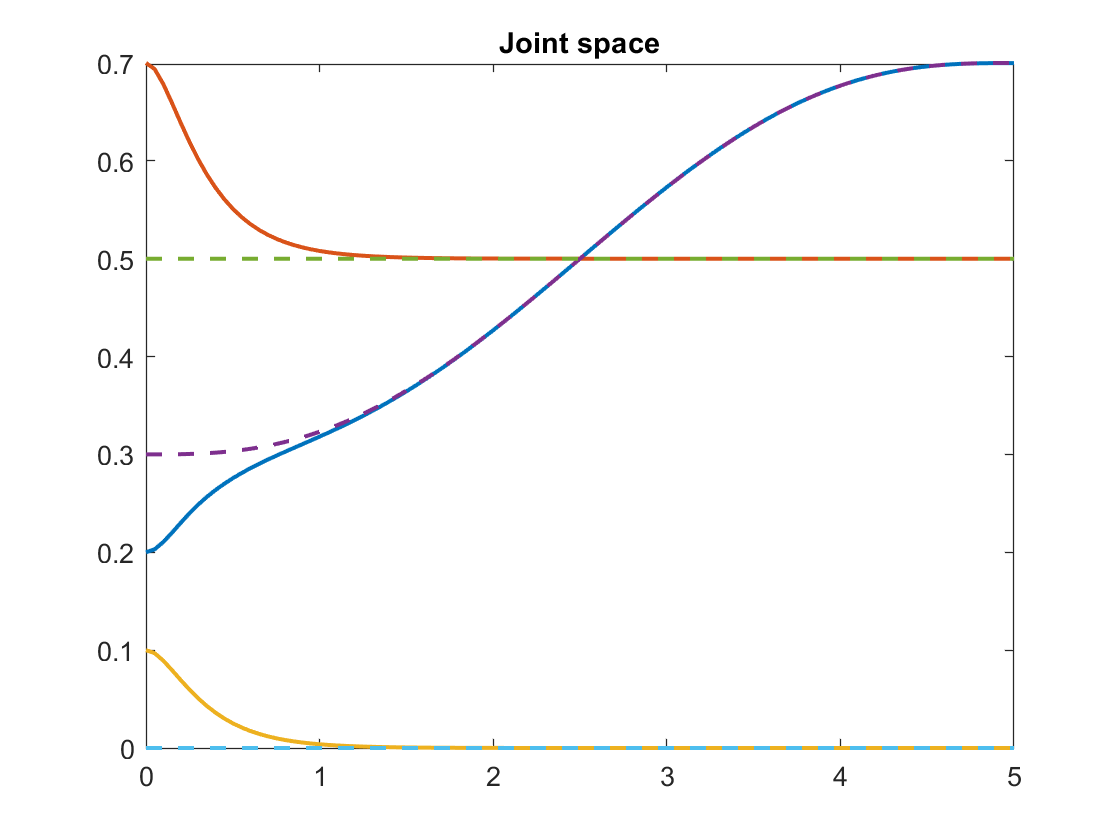

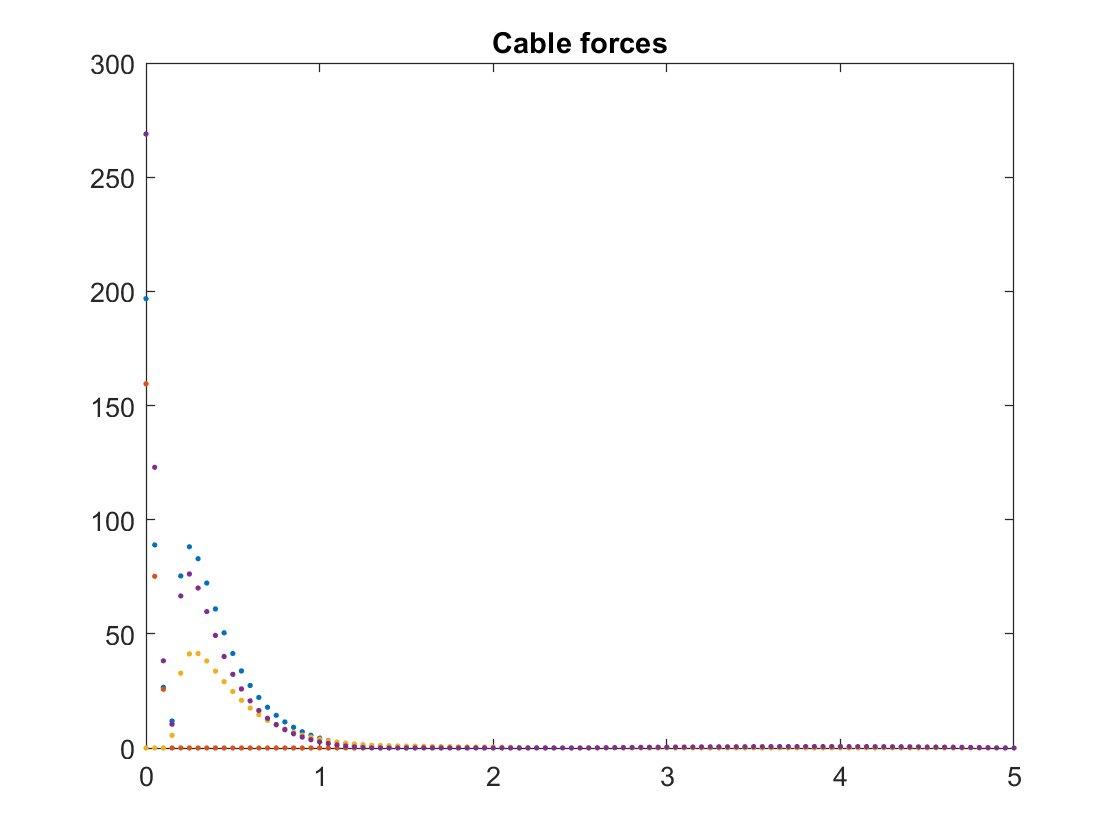

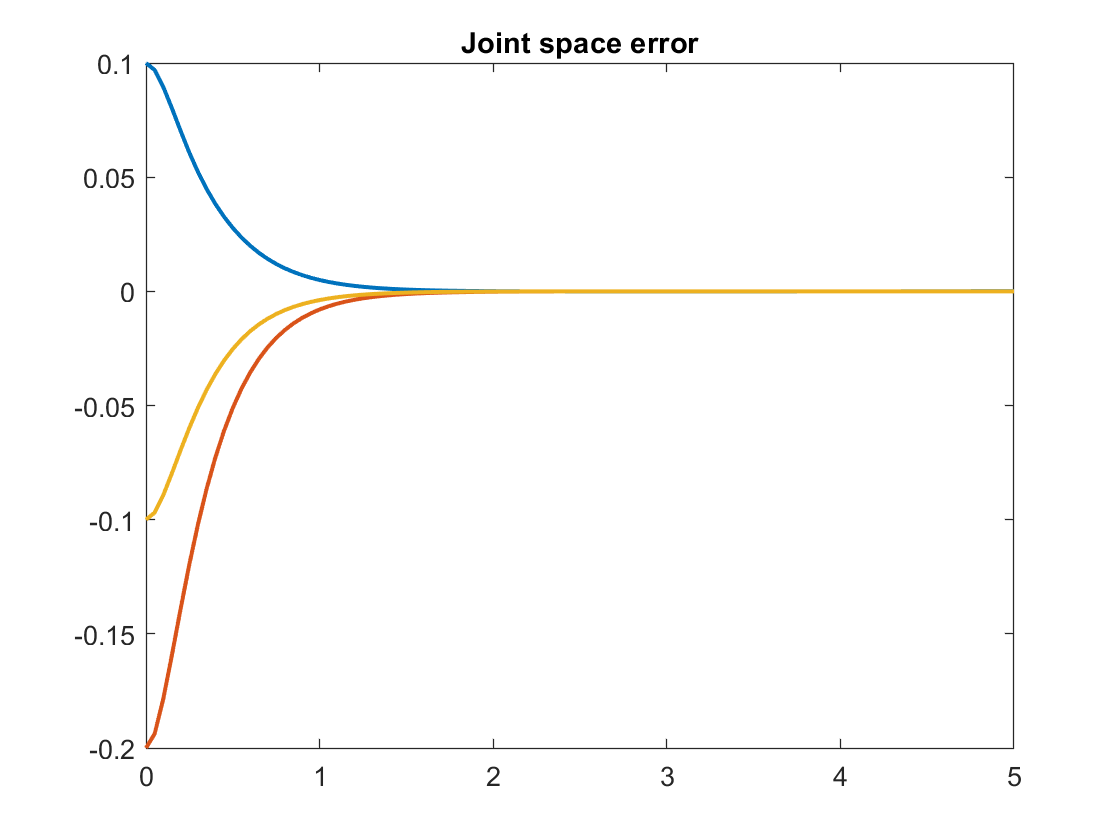

    figure; 

    plot(trajectory_ref.timeVector, force_soln, '.', 'LineWidth', 1.5);
    title('Cable forces');

Finally the tracking error:

    figure; 
    plot(trajectory_ref.timeVector, cell2mat(trajectory_ref.q) - q_soln, 'LineWidth', 1.5);
    title('Joint space error');
end